# Simulation Dynamics

This section presents the simulation dynamics of the model.

We begin by computing the baseline transition path of the economy under Business-As-Usual assumptions.

We then introduce an alternative carbon-policy scenario and solve for the corresponding transition to a net-zero economy.

Finally, we compare the two deterministic trajectories to assess the macroeconomic and climate implications of stronger mitigation efforts.

## I. Initialization of the path of the model

We start by loading the model using Dynare:

dynare model_file

Starting Dynare (version 6.4).
Calling Dynare with arguments: none
Starting preprocessing of the model file ... 
Found 19 equation(s). 
Evaluating expressions... 
Computing static model derivatives (order 1). 
Normalizing the static model... 
Normalization failed with cutoff, trying symbolic normalization... 
Finding the optimal block decomposition of the static model... 
10 block(s) found: 
  9 recursive block(s) and 1 simultaneous block(s). 
  the largest simultaneous block has 7 equation(s) 
                                 and 7 feedback variable(s). 
Computing dynamic model derivatives (order 2). 
Normalizing the dynamic model... 
Finding the optimal block decomposition of the dynamic model... 
3 block(s) found: 
  2 recursive block(s) and 1 simultaneous block(s). 
  the largest simultaneous block has 7 equation(s) 
                                 and 4 feedback variable(s). 
Preprocessing completed


STEADY-STATE RESULTS:

Z       		 23.3662
L       		 10.48
gZ      		 0
SIG     		 0
THETA1  		 0
delthet 		 0
M       		 2790.93
y       		 0.957955
c       		 0.957955
r       		 1.00503
w       		 0.93576
h       		 1.02372
mu      		 0
d       		 0.93576
tau     		 0
E       		 0
T       		 6.41914
tau_USD 		 0
s_a     		 1
Total computing time : 0h00m01s
Note: 1 warning(s) encountered in the preprocessor
Note: warning(s) encountered in MATLAB/Octave code



% solve the path for business as usual
[y_guess,oo_,M_]		= EP_paths_init(oo_,M_,options_,exo_init_ts);
[y_bau] 				= EP_deterministic_path(y_guess,exo_init_ts,oo_,M_,options_);


--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 6.01356,	 time = 0.176
Iter: 2,	 err. = 1.13687e-13,	 time = 0.066

Total time of simulation: 0.357.
--------------------------------------------------------



## II. Scenario: transition with alternative carbon policy

### A. Solving the transition to net zero economy

We now consider a transition scenario in which the implementation of the carbon tax is modified. This is captured by updating the terminal state of the model with a new value of the policy parameter `varphi`. The routine `update_terminal_state` adjusts the long run conditions of the economy (for example, the terminal carbon stock and productivity) consistently with this new policy.

In the business-as-usual scenario, it is assumed that carbon tax path does not materializes: phi*tau with phi=0. But the tax path consistent with Paris-Agreement actually exists:

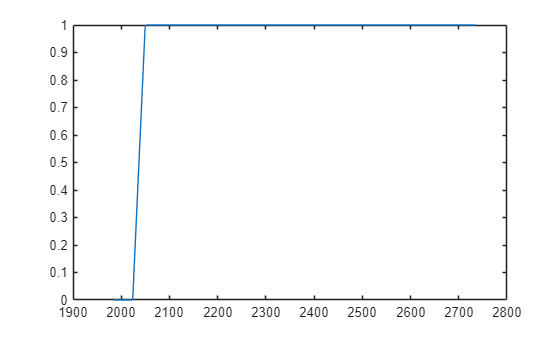

figure;
plotds('e_tau',exo_init_ts)

where 1 means net zero transition.

Using the updated structures `(oo_nz0, M_nz0)` and the corresponding initial guess `y_nz0`, we then recompute the deterministic transition path with `EP_deterministic_path`. The resulting path describes how the economy evolves under this alternative carbon policy scenario.

% Update terminal state for a scenario with varphi = 1
[y_nz0, oo_nz0, M_nz0] = update_terminal_state('varphi', 1, ...
                                               oo_, M_, exo_init_ts, y_guess);

% Step 1: Compute the deterministic path under the new policy
[y_nz0] = EP_deterministic_path(y_nz0, exo_init_ts, oo_nz0, M_nz0, options_);


dates_vec = <dates: 1985Q1, 1985Q2, ..., 2734Q1, 2734Q2>



--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 6.01356,	 time = 0.064
Iter: 2,	 err. = 0.432327,	 time = 0.07
Iter: 3,	 err. = 0.000983075,	 time = 0.062
Iter: 4,	 err. = 3.21332e-07,	 time = 0.064

Total time of simulation: 0.418.
--------------------------------------------------------



### B. Plotting the final figure

We now compare the deterministic transition of the economy under two policy scenarios:

- a Business-As-Usual (BAU) path `y_bau`,

- a Paris-Agreement-style path `y_nz0`, where the carbon policy is tightened.

The figure below plots key macroeconomic and climate variables under both scenarios over the period 2000–2100. This highlights how output, consumption, labor, damages, the carbon tax in USD, emissions, temperature, and the carbon stock respond to stronger climate policy relative to BAU.

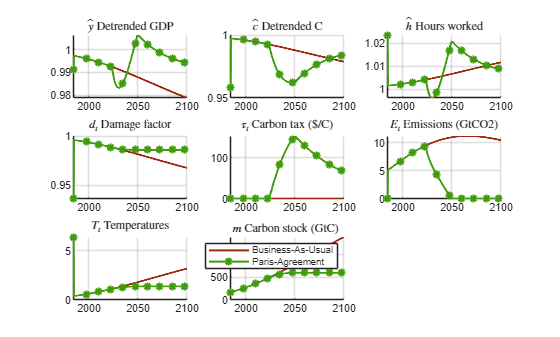

nx = 3;ny = 3;varnames=char('y','c','h','d','tau_USD','E','T','M');
nn=size(varnames,1);
figure('Name','Figure 3: Comparison of transitions (deterministic)');
for i1 =1:nn
	subplot(nx,ny,i1)
	idx = strmatch(deblank(varnames(i1,:)),M_.endo_names,'exact');
	hold on;
	plotds(varnames(i1,:),y_bau,'Color',[156, 40, 14]/255,'LineWidth',1.5,'MarkerIndice',1:50:size(y_bau,1))
	plotds(varnames(i1,:),y_nz0,'*-','Color',[64, 156, 14]/255,'LineWidth',1.5,'MarkerIndice',1:50:size(y_nz0,1))
	hold off;
	grid on
	title(['$' M_.endo_names_tex{idx} '$ ' M_.endo_names_long{idx}],'Interpreter','latex')
	xlim([1984 2100])
end
legend('Business-As-Usual','Paris-Agreement')

## III. Alternative transitions paths